# Communication systems laboratory Lab4

## [PART1]

### (1)

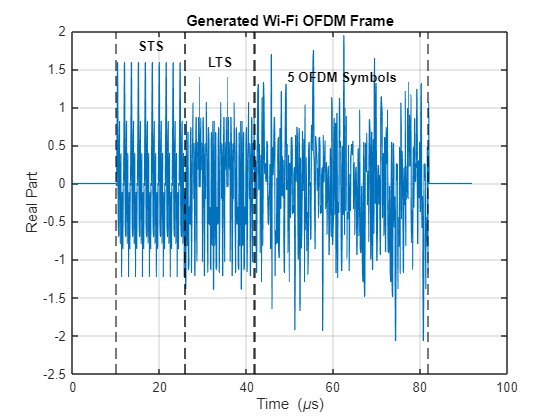

clear all; close all; clc;
FFT_size = 64;
cp_size = 16;
fs = 10e6;
sc_space = fs/FFT_size;
%% 802.11a/g subcarrier allocation
active_sc  = [-26:-1 1:26];           % 52 active subcarriers
pilot_sc = [-21 -7 7 21];           % 4 pilot tones
data_sc  = setdiff(active_sc, pilot_sc); % 48 data tones

num_ofdm_symbols = 5;
pad_len = 100;

%% (1) Generate a frame with STS, LTS, and 5 OFDM symbols
sts = gen_sts();
lts = gen_lts();
[ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc);

sts = sts / rms(sts);
lts = lts / rms(lts);
ofdm_data = ofdm_data / rms(ofdm_data);

tx_frame = [zeros(pad_len,1); sts; lts; ofdm_data; zeros(pad_len,1)];

region_names = {'STS', 'LTS', '5 OFDM Symbols'};
region_ranges = [
    pad_len + 1,                              pad_len + length(sts);
    pad_len + length(sts) + 1,                pad_len + length(sts) + length(lts);
    pad_len + length(sts) + length(lts) + 1,  pad_len + length(sts) + length(lts) + length(ofdm_data)
];

plot_td_signal(tx_frame, fs, 'Generated Wi-Fi OFDM Frame', 'Real', region_names, region_ranges);

### (2)

fc = 885e6;
tx_gain = 5;
rx_gain = 5;

% Use the frame generated in (1)
data = tx_frame;

% To ensure capturing a whole frame, receive longer than the transmitted frame
rx_length = 200 * (length(tx_frame) + 500);

% Check USRP connection
info = findsdru();

Checking radio connections...


while info.Status ~= "Success"
    release(radio_Tx);
    release(radio_Rx);
    pause(1);
    info = findsdru();
end

% Initialize USRP
[radio_Tx, radio_Rx] = USRP_init(fc, tx_gain, rx_gain, rx_length);

% Matched filter for STS detection
match_filter = conj(flipud(sts));

% Variables for repeated transmission
buffer = zeros(rx_length, 1);
tunderrun = 0;
toverflow = 0;
maxattempts = 50;
success = 0;
threshold = 1;
start_point = 0;

for attempt = 1:maxattempts

    % Transmit the generated frame
    tunderrun = radio_Tx(data);

    % Receive signal
    [received_signal, ~, toverflow] = step(radio_Rx);

    % STS matched filter
    corr = abs(conv(received_signal, match_filter));
    maxval = max(corr);

    if maxval >= threshold

        % Store received signal
        buffer(:,1) = received_signal;

        % Find the approximate STS position
        [~, peak_idx] = max(corr);

        % Since the matched filter peak appears near the matched segment,
        % estimate the STS start point from the peak position
        sts_start = peak_idx - 160 + 1;

        % The transmitted frame has 100 zeros before STS
        frame_start = sts_start - pad_len;

        if frame_start < 1
            frame_start = 1;
        end

        frame_end = frame_start + length(tx_frame) - 1;

        if frame_end > length(buffer)
            frame_end = length(buffer);
        end

        start_point = frame_start;
        success = 1;
        break

    else
        fprintf("Attempt %d: max corr = %.6f\n", attempt, maxval);
    end
end

Attempt 1: max corr = 0.008521
Attempt 2: max corr = 0.010597
Attempt 3: max corr = 0.009459
Attempt 4: max corr = 0.008804
Attempt 5: max corr = 0.010358
Attempt 6: max corr = 0.009879
Attempt 7: max corr = 0.008820
Attempt 8: max corr = 0.009248
Attempt 9: max corr = 0.008617
Attempt 10: max corr = 0.010517
Attempt 11: max corr = 0.008874
Attempt 12: max corr = 0.011135
Attempt 13: max corr = 0.009276


if success
    disp("SUCCESS!");
else
    release(radio_Tx);
    release(radio_Rx);
    error("FAIL! No valid frame detected.");
end

SUCCESS!


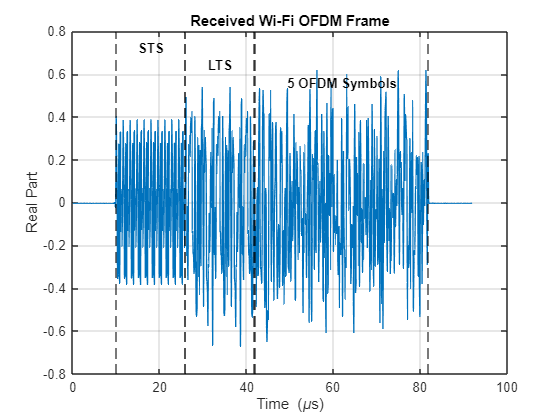

% Extract received frame
rx_frame = buffer(start_point:frame_end);

% Release USRP resources
release(radio_Tx);
release(radio_Rx);

% Mark STS, LTS, and OFDM data symbols
rx_region_names = {'STS', 'LTS', '5 OFDM Symbols'};

rx_region_ranges = [
    pad_len + 1,                              pad_len + length(sts);
    pad_len + length(sts) + 1,                pad_len + length(sts) + length(lts);
    pad_len + length(sts) + length(lts) + 1,  pad_len + length(sts) + length(lts) + length(ofdm_data)
];

% Plot received frame in time domain
plot_td_signal(rx_frame, fs, 'Received Wi-Fi OFDM Frame', 'Real', rx_region_names, rx_region_ranges);

### (3)

We ensure the OFDM sample rate is 10 MHz by setting the USRP master clock rate to 100 MHz and configuring both the interpolation factor and decimation factor to 10. Therefore, the transmit baseband sample rate is 100M/10 = 10 MHz, and the receive baseband sample rate is also 100M/10 = 10 MHz. In the transmit chain, interpolation is applied before the DAC to raise the baseband sampling rate to the internal USRP clock rate. In the receive chain, decimation is applied after the ADC to reduce the internal sampling rate back to the desired baseband rate. Hence, both transmission and reception operate at the required OFDM sample rate of 10 MHz. 

### (4)

mf  = conj(flipud(sts));

mf_result = abs(conv(rx_frame, mf));

[~, sts_end] = max(mf_result);

fprintf("Beginning of first long training symbol = %d\n", sts_end + 33);

Beginning of first long training symbol = 293


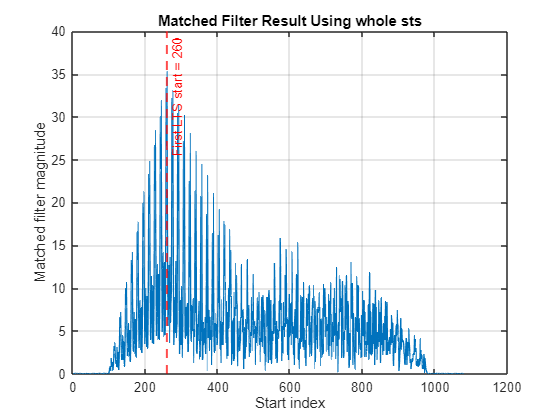

first_lts_start = sts_end + 33;

figure;
plot(1:length(mf_result), mf_result, 'LineWidth', 1);
grid on;
xlabel('Start index');
ylabel('Matched filter magnitude');
title('Matched Filter Result Using whole sts');

hold on;
xline(sts_end, '--r', sprintf('First LTS start = %d', sts_end), 'LineWidth', 1.5);

### (5)

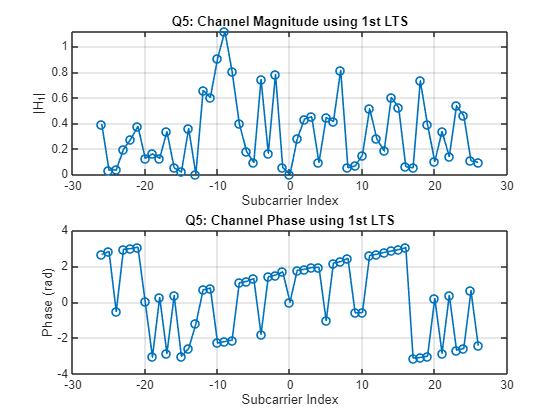

%% Q5
% 取出第一個 Long Training Symbol，並用它估測 channel

rx_lts_1 = extractLTS(rx_frame, first_lts_start, 1, FFT_size);
lts_f_known = fftshift(fft(lts(33:96)));
H1 = estimateChannelFromLTS(rx_lts_1, lts_f_known);
% 題目要求畫 subcarrier -26 到 26
% 這裡包含 0 subcarrier，但 DC 通常沒有資料，所以中間可能會是 0 或怪點
used_subc = -26:26;

% 將 subcarrier index 轉換成 fftshift 後的 MATLAB array index
idx = used_subc + FFT_size/2 + 1;

figure;

% 畫 channel magnitude
subplot(2,1,1);
plot(used_subc, abs(H1(idx)), '-o', 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier Index');
ylabel('|H_1|');
title('Q5: Channel Magnitude using 1st LTS');

% 畫 channel phase
subplot(2,1,2);
plot(used_subc, angle(H1(idx)), '-o', 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier Index');
ylabel('Phase (rad)');
title('Q5: Channel Phase using 1st LTS');

### (6)

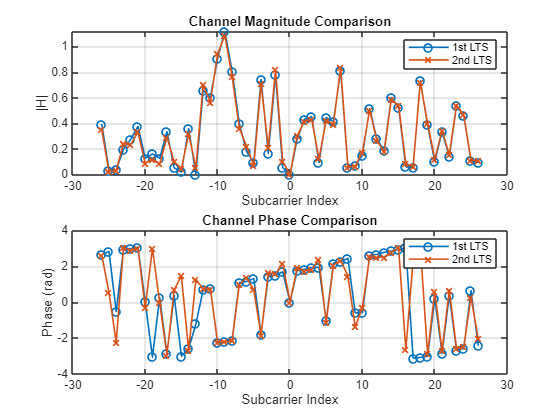

%% Q6
% 取出第二個 LTS，也做 channel estimation
% 然後比較 H1 和 H2 的 magnitude / phase 是否接近

rx_lts_2 = extractLTS(rx_frame, first_lts_start, 2, FFT_size);
lts_f_known = fftshift(fft(lts(97:160)));
H2 = estimateChannelFromLTS(rx_lts_2, lts_f_known);

% 畫出第一個 LTS 和第二個 LTS 估測到的 channel 比較
plotChannelCompare(H1, H2);

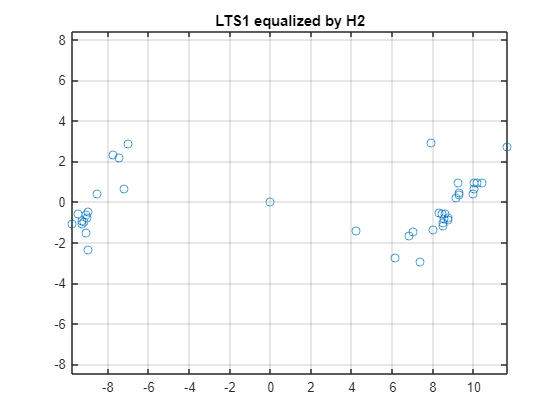

% equalizer check
active_idx = active_sc + FFT_size/2 + 1;

rx_lts1_test = rx_frame(first_lts_start : first_lts_start + FFT_size - 1);
rx_lts2_test = rx_frame(first_lts_start + FFT_size : first_lts_start + 2*FFT_size - 1);

Y_lts1_test = fftshift(fft(rx_lts1_test(:), FFT_size));
Y_lts2_test = fftshift(fft(rx_lts2_test(:), FFT_size));
X12 = equalizeSymbol(Y_lts1_test, H2);   % LTS1 用 H2
X21 = equalizeSymbol(Y_lts2_test, H1);   % LTS2 用 H1

figure;
plot(real(X12(active_idx)), imag(X12(active_idx)), 'o');
grid on; axis equal;
title('LTS1 equalized by H2');

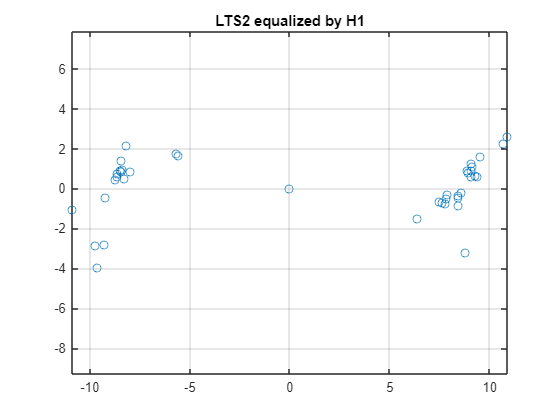

figure;
plot(real(X21(active_idx)), imag(X21(active_idx)), 'o');
grid on; axis equal;
title('LTS2 equalized by H1');

### (7)


$$\mathrm{subcarrier}\;\mathrm{spacing}=\frac{\mathrm{fs}}{\mathrm{FFTsize}}=\frac{{10}^6 }{64}=156\ldotp 25\mathrm{kHz}$$


In USRP transmission, fc = 885MHz


$$\begin{array}{l}
\mathrm{subcarrier}-26:885\mathrm{MHz}-26*156\ldotp 25\mathrm{kHz}=880\ldotp 9375\mathrm{MHz}\\
\mathrm{subcarrier}\;0:885\mathrm{MHz}\\
\mathrm{subcarrier}\;26:885\mathrm{MHz}+26*156\ldotp 25\mathrm{kHz}=889\ldotp 0625\mathrm{MHz}
\end{array}$$


### (8)

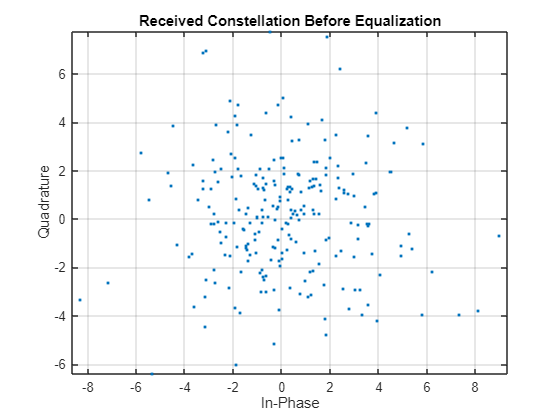

%% Q8
% 取出 data symbols，並在 equalization 前畫星座圖
% 此時因為還沒除掉 channel，所以星座圖可能會被旋轉、縮放或拉歪

num_sym = 5;

% 從 rx_frame 裡面取出 5 個 OFDM symbols，每個都包含 CP
second_lts_start = first_lts_start + 64;
data_start = second_lts_start + 64;

rx_symbols = extractOFDMSymbols(rx_frame, data_start, FFT_size, cp_size, num_sym);

% 儲存 equalization 前的 data subcarriers
rx_data_before_eq = [];

sc2idx = @(k) k + FFT_size/2 + 1;
data_idx = sc2idx(data_sc);

for k = 1:num_sym
    % 對第 k 個 OFDM symbol 做 OFDM demodulation：
    % 移除 CP + FFT + fftshift
    Y = ofdmDemodSymbol(rx_symbols(:, k), FFT_size, cp_size);

    % 只取出 data subcarriers
    rx_data_before_eq = [rx_data_before_eq; Y(data_idx)];
end
% 畫 equalization 前的 constellation
plotConstellation(rx_data_before_eq, 'Received Constellation Before Equalization');

### (9)

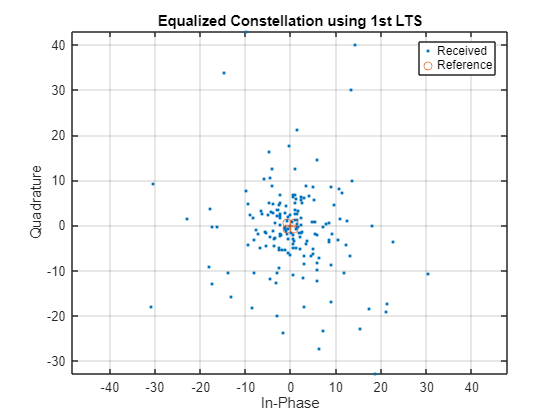

%% Q9
% 使用 Q5 和 Q6 估測出來的 channel 對 data symbols 做 equalization
% equalization 的概念：x_hat = Y / H

eq_data_1 = [];
eq_data_2 = [];

for k = 1:num_sym
    % OFDM demodulation
    Y = ofdmDemodSymbol(rx_symbols(:, k), FFT_size, cp_size);

    % 分別使用第一個 LTS 和第二個 LTS 的 channel estimate 做 equalization
    x_hat_1 = equalizeSymbol(Y, H1);
    x_hat_2 = equalizeSymbol(Y, H2);

    % 只取出 data subcarriers
    eq_data_1 = [eq_data_1; x_hat_1(data_idx)];
    eq_data_2 = [eq_data_2; x_hat_2(data_idx)];
end

% 畫 equalization 後的 constellation
% tx_data_syms(:) 是原本傳送的 QPSK reference symbols
plotConstellation(eq_data_1, 'Equalized Constellation using 1st LTS', tx_data_syms(:));

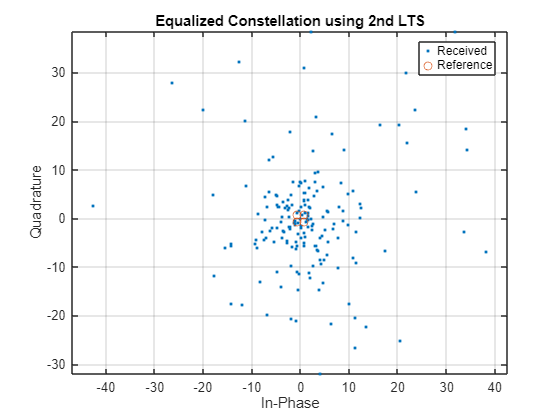

plotConstellation(eq_data_2, 'Equalized Constellation using 2nd LTS', tx_data_syms(:));

### (10)

%% Q10
% 利用 zero padding 區域估計 noise power
% 利用 data symbol 區域估計 signal power
% 最後計算 SNR

num_sym = 5;

% 前面的 zero padding 區間
zero_pad_1 = [1, 100];

% 後面的 zero padding 區間
zero_pad_2 = [length(rx_frame)-99, length(rx_frame)];

% 計算 SNR
[snr_dB, sig_pow, noise_pow] = calcFrameSNR( ...
    rx_frame, data_start, FFT_size, cp_size, num_sym, zero_pad_1, zero_pad_2);

fprintf('Signal power = %.6f\n', sig_pow);

Signal power = 0.166426


fprintf('Noise power  = %.6f\n', noise_pow);

Noise power  = 0.000113


fprintf('SNR = %.3f dB\n', snr_dB);

SNR = 31.670 dB


## [Functions]

% gen_sts
% Usage:
%   sts = gen_sts()
% Input:
%   None
% Output:
%   sts : time-domain 802.11a/g short training sequence, length = 160 samples
function sts = gen_sts()
    FFT_size = 64;

    short_sc = [-24 -20 -16 -12 -8 -4 4 8 12 16 20 24];
    short_val = sqrt(13/6) * ...
        [1+1j; 1+1j; -1-1j; -1-1j; 1+1j; 1+1j; ...
         -1-1j; -1-1j; -1-1j; 1+1j; -1-1j; 1+1j];

    sts_f = zeros(FFT_size, 1);
    sts_f(short_sc + FFT_size/2 + 1) = short_val;

    sts_64 = ifft(ifftshift(sts_f), FFT_size);
    sts_16 = sts_64(1:16);
    sts = repmat(sts_16, 10, 1);
end


% gen_lts
% Usage:
%   lts = gen_lts()
% Input:
%   None
% Output:
%   lts : time-domain 802.11a/g long training sequence, length = 160 samples
%         structure = [32-sample CP; 64-sample LTS; 64-sample LTS]
function lts = gen_lts()
    FFT_size = 64;

    lts_sc = -26:26;
    lts_val = [ ...
         1;  1; -1; -1;  1;  1; -1;  1; -1;  1;  1;  1;  1;  1;  1; -1; ...
        -1;  1;  1; -1;  1; -1;  1;  1;  1;  1; ...
         0; ...
         1; -1; -1;  1;  1; -1;  1; -1;  1; -1; -1; -1; -1; -1;  1;  1; ...
        -1; -1;  1; -1;  1; -1;  1;  1;  1;  1];

    lts_f = zeros(FFT_size, 1);
    lts_f(lts_sc + FFT_size/2 + 1) = lts_val;

    lts_64 = ifft(ifftshift(lts_f), FFT_size);
    lts = [lts_64(end-31:end); lts_64; lts_64];
end


% gen_ofdm_symbol
% Usage:
%   x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
% Input:
%   data_syms  : 48x1 complex vector, data symbols on data subcarriers
%   pilot_syms : 4x1 vector, pilot symbols on pilot subcarriers
%   data_sc    : data subcarrier indices
%   pilot_sc   : pilot subcarrier indices
% Output:
%   x_cp       : one OFDM symbol with cyclic prefix, length = 80 samples
function x_cp = gen_ofdm_symbol(data_syms, pilot_syms, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    X = zeros(FFT_size, 1);
    X(data_sc + FFT_size/2 + 1) = data_syms;
    X(pilot_sc + FFT_size/2 + 1) = pilot_syms;

    x = ifft(ifftshift(X), FFT_size);
    x_cp = [x(end-cp_size+1:end); x];
end


% gen_ofdm_data
% Usage:
%   [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
% Input:
%   num_ofdm_symbols : number of OFDM symbols to generate
%   data_sc          : data subcarrier indices
%   pilot_sc         : pilot subcarrier indices
% Output:
%   ofdm_data     : concatenated time-domain OFDM symbols with cyclic prefix
%   tx_bits       : transmitted bits on data subcarriers
%   tx_data_syms  : transmitted 4-QAM symbols on data subcarriers
%   pilot_syms    : pilot symbols on pilot subcarriers
function [ofdm_data, tx_bits, tx_data_syms, pilot_syms] = gen_ofdm_data(num_ofdm_symbols, data_sc, pilot_sc)
    FFT_size = 64;
    cp_size = 16;

    num_data = length(data_sc);
    num_pilot = length(pilot_sc);

    tx_bits = randi([0 1], 2*num_data, num_ofdm_symbols);
    tx_data_syms = zeros(num_data, num_ofdm_symbols);
    pilot_syms = ones(num_pilot, num_ofdm_symbols);

    ofdm_data = zeros((FFT_size + cp_size) * num_ofdm_symbols, 1);

    for sym_idx = 1:num_ofdm_symbols
        data_syms = qammod(tx_bits(:, sym_idx), 4, ...
            'InputType', 'bit', 'UnitAveragePower', true);

        tx_data_syms(:, sym_idx) = data_syms;

        X = zeros(FFT_size, 1);
        X(data_sc + FFT_size/2 + 1) = data_syms;
        X(pilot_sc + FFT_size/2 + 1) = pilot_syms(:, sym_idx);

        x = ifft(ifftshift(X), FFT_size);
        x_cp = [x(end-cp_size+1:end); x];

        start_idx = (sym_idx - 1) * (FFT_size + cp_size) + 1;
        end_idx = sym_idx * (FFT_size + cp_size);
        ofdm_data(start_idx:end_idx) = x_cp;
    end
end


% plot_td_signal
% Usage:
%   plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
% Input:
%   x             : input signal in time domain
%   fs            : sampling rate in Hz
%   fig_title     : figure title
%   plot_mode     : 'Real', 'Imag', or 'Abs'
%   region_names  : 1xN cell array, label names of marked regions
%   region_ranges : Nx2 matrix, each row = [start_idx end_idx]
% Output:
%   None
%   This function plots a time-domain signal in microseconds and optionally
%   marks specified regions with vertical boundaries and labels
function plot_td_signal(x, fs, fig_title, plot_mode, region_names, region_ranges)
    t_us = (0:length(x)-1).' / fs * 1e6;

    switch lower(plot_mode)
        case 'real'
            y = real(x);
            y_label = 'Real Part';
        case 'imag'
            y = imag(x);
            y_label = 'Imaginary Part';
        case 'abs'
            y = abs(x);
            y_label = 'Magnitude';
        otherwise
            error('plot_mode must be ''Real'', ''Imag'', or ''Abs''.');
    end

    figure;
    plot(t_us, y, 'LineWidth', 1);
    grid on;
    xlabel('Time (\mus)');
    ylabel(y_label);
    title(fig_title);
    hold on;

    if nargin < 5 || isempty(region_names) || isempty(region_ranges)
        return;
    end

    yl = ylim;

    for k = 1:size(region_ranges, 1)
        idx_start = region_ranges(k, 1);
        idx_end = region_ranges(k, 2);

        xline(t_us(idx_start), '--k');
        xline(t_us(idx_end), '--k');

        text(mean(t_us(idx_start:idx_end)), yl(2) * (0.9 - 0.1*(k-1)), region_names{k}, ...
            'HorizontalAlignment', 'center', 'FontWeight', 'bold');
    end
end

function rx_lts = extractLTS(rx_frame, first_lts_start, which_lts, FFT_size)
% extractLTS
% 從 rx_frame 中取出指定的 Long Training Symbol。
%
% input:
% rx_frame        : 接收端完整 frame
% first_lts_start : 第一個 LTS body 的起始 index
% which_lts       : 要取第幾個 LTS，1 表示第一個，2 表示第二個
% FFT_size        : LTS 長度，通常等於 FFT size
%
% output:
% rx_lts          : 取出的 time-domain LTS，長度為 FFT_size

    if which_lts == 1
        start_idx = first_lts_start;
    elseif which_lts == 2
        start_idx = first_lts_start + FFT_size;
    else
        error('which_lts must be 1 or 2');
    end

    end_idx = start_idx + FFT_size - 1;

    if end_idx > length(rx_frame)
        error('LTS range exceeds rx_frame length');
    end

    rx_lts = rx_frame(start_idx:end_idx);
end


% setup_usrp
% Usage:
%   [tx_usrp, rx_usrp] = setup_usrp(fc, fs, tx_gain, rx_gain)
% Input:
%   fc      : carrier frequency in Hz
%   fs      : sampling rate in Hz
%   tx_gain : transmit gain in dB
%   rx_gain : receive gain in dB
% Output:
%   tx_usrp : configured USRP transmitter object
%   rx_usrp : configured USRP receiver object
function [tx_usrp, rx_usrp] = USRP_init(fc, tx_gain, rx_gain, rx_length)
    % master_clock_rate = 100e6;
    % interp_decim = master_clock_rate / fs;

    tx_usrp = comm.SDRuTransmitter( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'CenterFrequency',     fc, ...
        'InterpolationFactor',  10, ...
        'Gain',                tx_gain);

    rx_usrp = comm.SDRuReceiver( ...
        'Platform',            'N200/N210/USRP2', ...
        'IPAddress',           '192.168.10.2', ...
        'CenterFrequency',     fc, ...
        'Gain',                rx_gain, ...
        'SamplesPerFrame',     rx_length, ...
        'DecimationFactor',    10, ...
        'OutputDataType',      'double');
end

function H = estimateChannelFromLTS(rx_lts, lts_f_known)
% estimateChannelFromLTS
% 使用收到的 LTS 和已知的 LTS pattern 估測 channel。
%
% 原理：
% 頻域中接收訊號可以寫成
% Y = H * X
% 所以 channel estimate 為
% H = Y / X
%
% input:
% rx_lts      : time-domain received LTS
% lts_f_known : frequency-domain known LTS
%
% output:
% H           : frequency-domain channel estimate

    if length(rx_lts) ~= length(lts_f_known)
        error('rx_lts and lts_f_known must have the same length');
    end

    % 將收到的 LTS 轉到 frequency domain
    rx_lts_f = fftshift(fft(rx_lts));

    % 避免除以 0，只在 known LTS 非零的子載波上做 channel estimation
    H = zeros(size(rx_lts_f));
    valid_idx = abs(lts_f_known) > 1e-12;

    H(valid_idx) = rx_lts_f(valid_idx) ./ lts_f_known(valid_idx);
end


function rx_symbols = extractOFDMSymbols(rx_frame, data_start, FFT_size, cp_size, num_sym)
% extractOFDMSymbols
% 從 rx_frame 中取出多個 OFDM data symbols。
%
% 注意：這裡取出的每個 OFDM symbol 都「包含 CP」。
%
% input:
% rx_frame   : 接收端完整 frame
% data_start : 第一個 data OFDM symbol 的起始 index，包含 CP
% FFT_size   : FFT size
% cp_size    : cyclic prefix 長度
% num_sym    : 要取出的 OFDM symbol 數量
%
% output:
% rx_symbols : 每一欄是一個 OFDM symbol，大小為
%              (FFT_size + cp_size) x num_sym

    sym_len = FFT_size + cp_size;
    rx_symbols = zeros(sym_len, num_sym);

    for k = 1:num_sym
        start_idx = data_start + (k-1)*sym_len;
        end_idx   = start_idx + sym_len - 1;

        if end_idx > length(rx_frame)
            error('OFDM symbol range exceeds rx_frame length');
        end

        rx_symbols(:, k) = rx_frame(start_idx:end_idx);
    end
end


function Y = ofdmDemodSymbol(rx_symbol_with_cp, FFT_size, cp_size)
% ofdmDemodSymbol
% 對單一 OFDM symbol 做 demodulation。
%
% 步驟：
% 1. 移除 CP
% 2. 做 FFT
% 3. fftshift，讓子載波順序變成 -32 到 31
%
% input:
% rx_symbol_with_cp : 含 CP 的 time-domain OFDM symbol
% FFT_size          : FFT size
% cp_size           : cyclic prefix 長度
%
% output:
% Y                 : frequency-domain received OFDM symbol

    if length(rx_symbol_with_cp) ~= (FFT_size + cp_size)
        error('Input symbol length must be FFT_size + cp_size');
    end

    % 移除 cyclic prefix
    rx_no_cp = rx_symbol_with_cp(cp_size+1:end);

    % 轉到 frequency domain
    Y = fftshift(fft(rx_no_cp, FFT_size));
end


function x_hat = equalizeSymbol(Y, H)
% equalizeSymbol
% 使用 channel estimate 對 received OFDM symbol 做 equalization。
%
% 原理：
% Y = H * X
% 所以 X 的估計值為
% x_hat = Y / H
%
% input:
% Y : received frequency-domain OFDM symbol
% H : estimated channel
%
% output:
% x_hat : equalized frequency-domain symbol

    if length(Y) ~= length(H)
        error('Y and H must have the same length');
    end

    x_hat = zeros(size(Y));

    % 避免除以太小的 H，造成數值爆掉
    valid_idx = abs(H) > 0.1;

    x_hat(valid_idx) = Y(valid_idx) ./ H(valid_idx);
end


function [snr_dB, sig_pow, noise_pow] = calcFrameSNR(rx_frame, data_start, FFT_size, cp_size, num_sym, zero_pad_1, zero_pad_2)
% calcFrameSNR
% 估計接收 frame 的 SNR。
%
% 方法：
% 1. data symbol 區域拿來估計 signal power
% 2. 前後 zero padding 區域拿來估計 noise power
% 3. SNR = 10 log10(signal power / noise power)
%
% input:
% rx_frame   : 接收端完整 frame
% data_start : data symbols 起始位置
% FFT_size   : FFT size
% cp_size    : cyclic prefix 長度
% num_sym    : data OFDM symbol 數量
% zero_pad_1 : 前面 zero padding 區間 [start, end]
% zero_pad_2 : 後面 zero padding 區間 [start, end]
%
% output:
% snr_dB     : SNR，單位 dB
% sig_pow    : signal power
% noise_pow  : noise power

    sym_len = FFT_size + cp_size;

    % data signal 區間
    sig_start = data_start;
    sig_end   = data_start + num_sym*sym_len - 1;

    if sig_end > length(rx_frame)
        error('Signal region exceeds rx_frame length');
    end

    if zero_pad_1(2) > length(rx_frame) || zero_pad_2(2) > length(rx_frame)
        error('Zero-padding region exceeds rx_frame length');
    end

    % 取出 signal region 和 noise region
    sig_region = rx_frame(sig_start:sig_end);
    noise_region = [rx_frame(zero_pad_1(1):zero_pad_1(2)); ...
                    rx_frame(zero_pad_2(1):zero_pad_2(2))];

    % 計算平均功率
    sig_pow = mean(abs(sig_region).^2);
    noise_pow = mean(abs(noise_region).^2);

    % 換成 dB
    snr_dB = 10 * log10(sig_pow / noise_pow);
end


function plotChannelCompare(H1, H2)
% plotChannelCompare
% 比較使用第一個 LTS 和第二個 LTS 估測出的 channel。
%
% 圖一：channel magnitude
% 圖二：channel phase
%
% 題目要求觀察 subcarrier -26 到 26。

    used_subc = -26:26;

    % fftshift 後 index 對應：
    % subcarrier 0 對應 index 33
    idx = used_subc + 33;

    figure;

    % 比較 magnitude
    subplot(2,1,1);
    plot(used_subc, abs(H1(idx)), '-o', 'LineWidth', 1.2); hold on;
    plot(used_subc, abs(H2(idx)), '-x', 'LineWidth', 1.2);
    xlabel('Subcarrier Index');
    ylabel('|H|');
    title('Channel Magnitude Comparison');
    legend('1st LTS', '2nd LTS');
    grid on;

    % 比較 phase
    subplot(2,1,2);
    plot(used_subc, angle(H1(idx)), '-o', 'LineWidth', 1.2); hold on;
    plot(used_subc, angle(H2(idx)), '-x', 'LineWidth', 1.2);
    xlabel('Subcarrier Index');
    ylabel('Phase (rad)');
    title('Channel Phase Comparison');
    legend('1st LTS', '2nd LTS');
    grid on;
end


function plotConstellation(sym, plot_title, ref_sym)
% plotConstellation
% 畫星座圖。
%
% input:
% sym        : 要畫的 received 或 equalized symbols
% plot_title : 圖的標題
% ref_sym    : optional，原本 transmitted symbols，可以拿來對照

    figure;

    % 畫 received / estimated symbols
    plot(real(sym), imag(sym), '.');
    hold on;

    % 如果有提供 reference symbols，就一起畫出來比較
    if nargin >= 3 && ~isempty(ref_sym)
        plot(real(ref_sym), imag(ref_sym), 'o');
        legend('Received', 'Reference');
    end

    xlabel('In-Phase');
    ylabel('Quadrature');
    title(plot_title);
    axis equal;
    grid on;
end